# **Comparison of quasilinear KZK solutions and the experimental results**

**2023-05-05**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

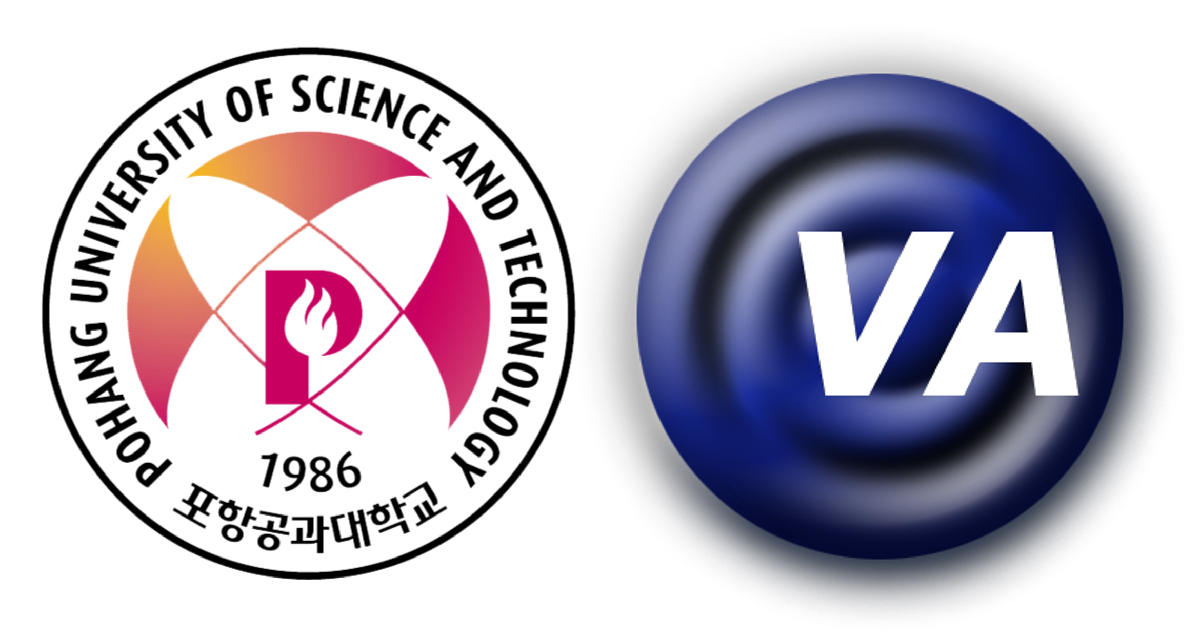

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

air = importfile_air('air.txt');

## Quasilinear KZK solution for the difference frequency


$$p_{-} \left(r,z,\tau \right) =
\frac{1}{2j} q_{-} \left(r,z \right) e^{j\omega_{-} \tau} + \mathrm{c.c.}$$


where


$$q_{-} \left(r,z \right) \cong
\frac{-j p_{0a} p_{0b} \beta k_{-}^2 a^2}
{4 \rho_0 c_0^2 \alpha_{T}}
\frac{e^{-\alpha_{-}z}}{z}
D_{W} \left(\theta \right) D_{A} \left(\theta \right)
\exp{ \left( -\frac{1}{2} j k_{-} z \tan^2{\theta} \right)}$$



$$\bar{z}=\frac{1}{\beta \varepsilon k}
=\frac{1}{\beta} \frac{\rho c_0^2}{p_0} \frac{c_0}{2\pi f_0}
=\frac{\rho c_0^3}{2\pi f_0 \beta p_0}$$



$$p_0=\frac{\rho c_0^3}{2\pi f_0 \beta \bar{z}}$$



$$k_-^2=\left( \frac{2 \pi f_-}{c_0} \right)^2
=\frac{4\pi^2 f_a^2}{c_0^2}\left( \frac{f_{-}}{f_{a}} \right)^2$$



$$z_0 = \frac{1}{2}k_aa^2
= \frac{\pi f_a}{c_0} a^2$$



$$a^2 = \frac{z_0 c_0}{\pi f_a}$$



$$\alpha_-
=\frac{1}{l_{a-}}
=\frac{1}{l_{aa}} \left( \frac{l_{aa}}{l_{a-}} \right)
=\frac{1}{l_{aa}} \left( \frac{f_{-}}{f_{a}} \right)^2$$



$$z=\xi z_0$$



$$\alpha_T
=\alpha_a+\alpha_b-\alpha_-
=\frac{1}{l_{aa}}+\frac{1}{l_{ab}}-\frac{1}{l_{a-}}
=\frac{1}{l_{aa}} \left( 1 +\frac{l_{aa}}{l_{ab}}-\frac{l_{aa}}{l_{a-}} \right)
=\frac{1}{l_{aa}} \left( 1 + \left( \frac{f_{b}}{f_{a}} \right)^2 - \left( \frac{f_{-}}{f_{a}} \right)^2 \right)
=\frac{1}{l_{aa}} \left( 1 + \left( \frac{f_{a}-f_{-}}{f_{a}} \right)^2 - \left( \frac{f_{-}}{f_{a}} \right)^2 \right)
=\frac{1}{l_{aa}} \left( 1 + \left( 1-\frac{f_{-}}{f_{a}} \right)^2 - \left( \frac{f_{-}}{f_{a}} \right)^2 \right)
=\frac{2}{l_{aa}} \left( 1 - \frac{f_{-}}{f_{a}} \right)$$


when $\theta=0$,


$$q_{-} \left(z \right) \cong
\frac{-j p_{0a} p_{0b} \beta k_{-}^2 a^2}
{2 \rho_0 c_0^2 \alpha_{T}}
\frac{e^{-\alpha_{-}z}}{z}$$


% Interpolating the veclocity response of the transudcer
u_tq = @(f_tq, f_t, u_t) interp1(f_t, u_t, f_tq);

% acoustic pressure by acoustic velocity
p_ = @(u) air.rho*air.c0*u;

% wavenumber
k_ = @(f) 2*pi*f/air.c0;

% Absoption length
l_a = @(f_a) 1./(1.84e-11*f_a.^2);

% Shock formation distance
z_ = @(u_0a, f_a) (air.c0^2)./(air.beta*2*pi*f_a.*u_0a);

% Rayleigh distance
z0 = @(f, a) k_(f)*a^2/2;

% Quasilinear KZK solution
% q_ = @(f_a, f_diff, a, z, f_t, u_t) (air.rho^2*air.c0^2*u_tq(f_a,f_t,u_t)*u_tq(f_a-f_diff,f_t,u_t)*air.beta*(2*pi*f_diff/air.c0)^2*a^2)...
%     /(4*air.rho*air.c0^2*2*1.84e-11*f_a*(f_a-f_diff))...
%     *exp(-1.84e-11*f_diff^2*z)/z;
q_ = @(f_a, f_diff, a, z, f_t, u_t) (p_(u_tq(f_a,f_t,u_t))*p_(u_tq(f_a-f_diff,f_t,u_t))*air.beta*(k_(f_diff))^2*a^2)...
    /(2*air.rho*air.c0^2*(1/l_a(f_a)+1/l_a(f_a-f_diff)-1/l_a(f_diff)))...
    *exp(-z/(l_a(f_diff)))/z;



$$X=\frac{l_{aa}}{\bar{z}_a}
=\frac{\beta \varepsilon_a k_a}{\alpha_a}
=\frac{\beta u_a 2 \pi f_a}{1.84 \times 10^{-11}f_a^2 c_0^2}
=\frac{2 \pi \beta u_a}{1.84 \times 10^{-11}f_a c_0^2}$$


% Gol'dberg number
x_ = @(u_0a, f_a) (air.beta*2*pi*u_0a)...
    /(1.84e-11*f_a*air.c0^2);


$$Y=\frac{l_{aa}}{z_{0a}}
=\frac{1}{\alpha_a \frac{1}{2}k_aa^2}
=\frac{1}{1.84 \times 10^{-11}f_a^2 \frac{1}{2}k_a a^2}
=\frac{c_0}{1.84 \times 10^{-11}f_a^2 \pi f_a a^2}
=\frac{c_0}{1.84 \times 10^{-11} \pi a^2 f_a^3}$$


% Inverse normalized Rayleigh distance by absorption length
y_ = @(f_a, a) air.c0...
    /(1.84e-11*f_a^3*pi*a^2);

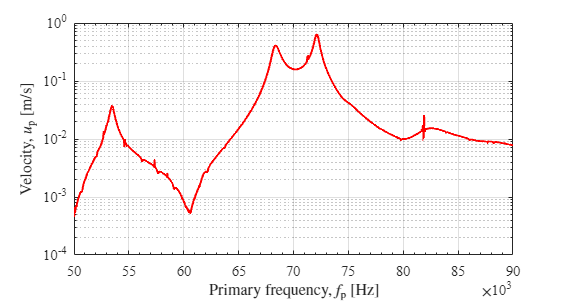

% the carrier frequency
kcy.f_a = 72.2e3;
% the radius of plate
kcy.a   = 50e-3; 
% kcy.a   = 25e-3;    % for 1/2 radius
% the measurement distance
kcy.z   = 1;

% from KCY, kcy - mfu - freq vs. measured vel (velocity.xlsx)
kcy.fr_kcy_mfu = importfile_fr('kcy - freq vs. measured vel (velocity.xlsx).txt');
kcy.f_t = kcy.fr_kcy_mfu.freq';
kcy.u_t = kcy.fr_kcy_mfu.res';
% kcy.u_t = kcy.fr_kcy_mfu.res'*0.3; % for 30 [%] intensity

% from KCY, kcy - mdfp - diff freq vs. SPL (DFW_SPL_1m.xlsx)
kcy.fr_kcy_mdfp    = importfile_fr('kcy - diff freq vs. SPL (DFW_SPL_1m.xlsx).txt');
kcy.f_diff_e    = kcy.fr_kcy_mdfp.freq';
kcy.spl_diff_e  = kcy.fr_kcy_mdfp.res';

createfigure_xy_multi(kcy.f_t,kcy.u_t, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',10,3);

l_a(kcy.f_a)

ans = 10.4258

z_(u_tq(kcy.f_a,kcy.f_t,kcy.u_t), kcy.f_a)

ans = 0.3587

x_(u_tq(kcy.f_a,kcy.f_t,kcy.u_t), kcy.f_a)

ans = 29.0631

y_(kcy.f_a, kcy.a)

ans = 6.3063

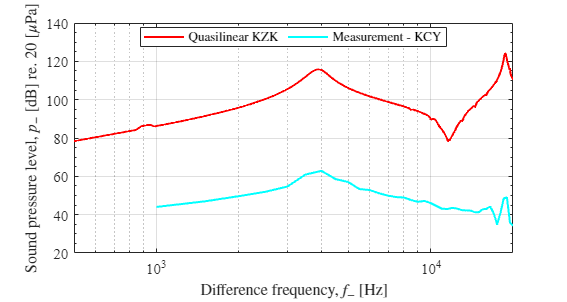


f_n = 1001;
kcy.f_diff  = logspace(log10(500),log10(2e4),f_n);
kcy.q_   = zeros(1,f_n);
for i=1:f_n
    kcy.q_(i) = q_(kcy.f_a, kcy.f_diff(i), kcy.a, kcy.z, kcy.f_t, kcy.u_t);
end

createfigure_xy_multi_sep([kcy.f_diff kcy.f_diff_e],[20*log10(kcy.q_/20e-6) kcy.spl_diff_e],[numel(kcy.f_diff) numel(kcy.f_diff_e)],...
    'Difference frequency, $f_{-}$ [Hz]','Sound pressure level, $p_{-}$ [dB] re. 20 $[\mu \mathrm{Pa}]$', ...
    'log','linear','centimeters',10,3,'',["Quasilinear KZK" "Measurement - KCY"],2);

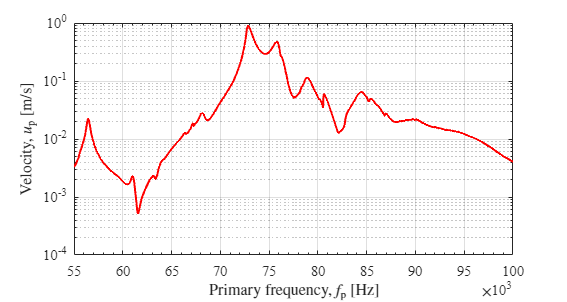

% the carrier frequency
obs.f_a = 72.8e3;
% the radius of plate
obs.a   = 50e-3; 
% obs.a   = 25e-3;    % for 1/2 radius
% the measurement distance
obs.z   = 1;

% from obs, obs - mfu - freq vs. measured vel (velocity.xlsx)
obs.fr_obs_mfu = importfile_fr('obs - freq vs. measured vel (SPPALs_Exp_Results_Total_modified_by_WJ (230505).xlsx).txt');
obs.f_t = obs.fr_obs_mfu.freq';
obs.u_t = obs.fr_obs_mfu.res'*10;
% obs.u_t = obs.fr_obs_mfu.res'*0.3; % for 30 [%] intensity

% from obs, obs - mdfp - diff freq vs. SPL (DFW_SPL_1m.xlsx)
obs.fr_obs_mdfp    = importfile_fr('obs - diff freq vs. SPL (SPPALs_Exp_Results_Total_modified_by_WJ (230505).xlsx).txt');
obs.f_diff_e    = obs.fr_obs_mdfp.freq';
obs.spl_diff_e  = obs.fr_obs_mdfp.res';

createfigure_xy_multi(obs.f_t,obs.u_t, ...
    'Primary frequency, $f_\mathrm{p}$ [Hz]','Velocity, $u_\mathrm{p}$ [m/s]', ...
    'linear','log','centimeters',10,3);

l_a(obs.f_a)

ans = 10.2546

z_(u_tq(obs.f_a,obs.f_t,obs.u_t), obs.f_a)

ans = 0.2458

x_(u_tq(obs.f_a,obs.f_t,obs.u_t), obs.f_a)

ans = 41.7196

y_(obs.f_a, obs.a)

ans = 6.1517

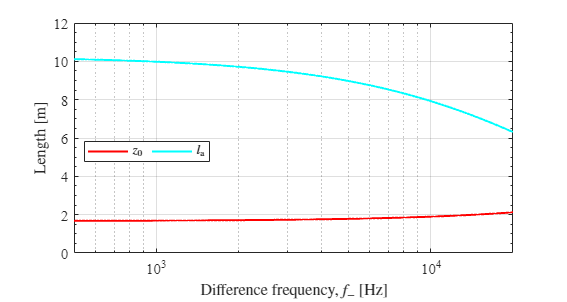


f_n = 1001;
obs.f_diff  = logspace(log10(500),log10(2e4),f_n);
obs.q_   = zeros(1,f_n);
for i=1:f_n
    obs.q_(i) = q_(obs.f_a, -obs.f_diff(i), obs.a, obs.z, obs.f_t, obs.u_t);
end

obs.z0 = z0(obs.f_a+obs.f_diff,obs.a);
obs.l_a = l_a(obs.f_a+obs.f_diff);
% obs.l_D = z_(u_tq(obs.f_a+obs.f_diff,obs.f_t,obs.u_t), obs.f_a+obs.f_diff);

createfigure_xy_multi(obs.f_diff, [obs.z0; obs.l_a], ...
    'Difference frequency, $f_{-}$ [Hz]','Length $\left[\mathrm{m}\right]$', ...
    'log','linear','centimeters',10,3,'',["$z_0$" "$l_\mathrm{a}$"],2)

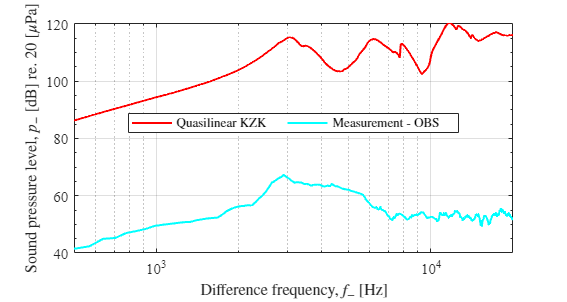

createfigure_xy_multi_sep([obs.f_diff obs.f_diff_e],[20*log10(obs.q_/20e-6) obs.spl_diff_e],[numel(obs.f_diff) numel(obs.f_diff_e)],...
    'Difference frequency, $f_{-}$ [Hz]','Sound pressure level, $p_{-}$ [dB] re. 20 $[\mu \mathrm{Pa}]$', ...
    'log','linear','centimeters',10,3,'',["Quasilinear KZK" "Measurement - OBS"],2);